# Homework 3

## [✔] ADSI Problem 2.1: Implementation of All-zero lattice filters

Work you way through the MATLAB code in Figure 9.26 and make sure you understand what is going on.  

Code can be found in azlatfilt.m.

## [✔] ADSI Problem 2.2: Find impulse response of an all-zero lattice filter

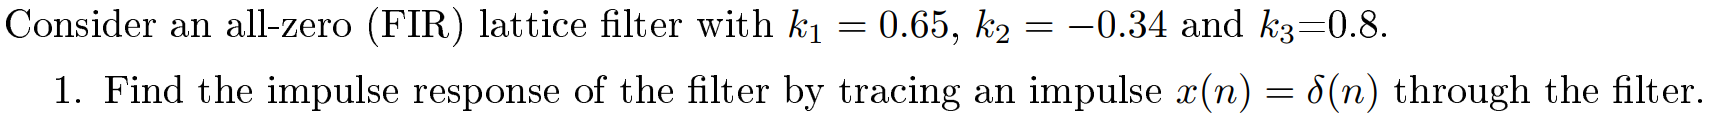

Since the lattice filter has three reflection coefficients, it is a 3-stage all-zero lattice filter.

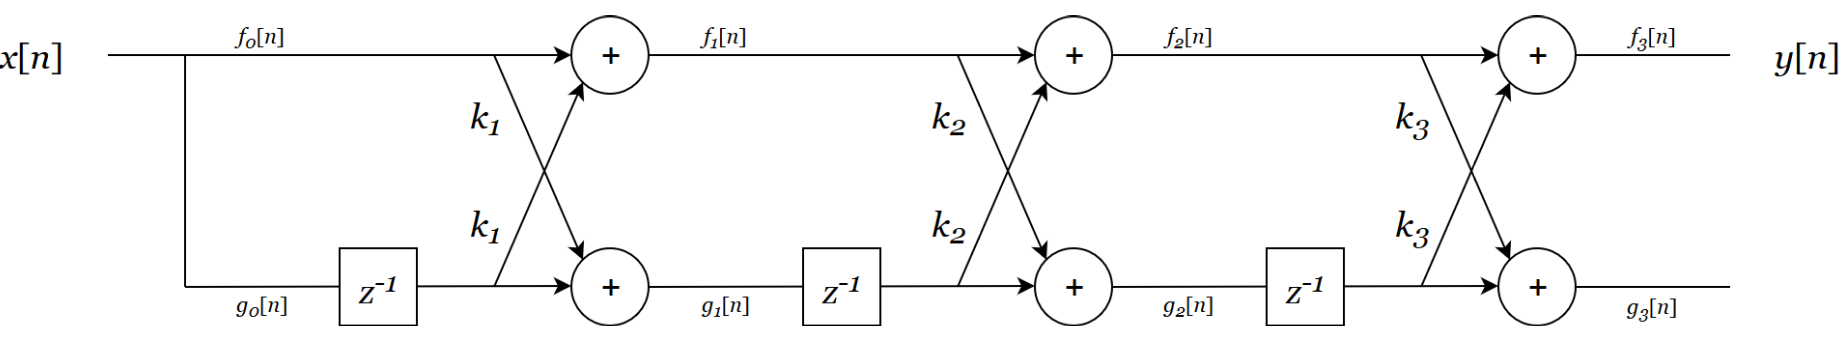

Here are the formulas needed to trace through the filter.

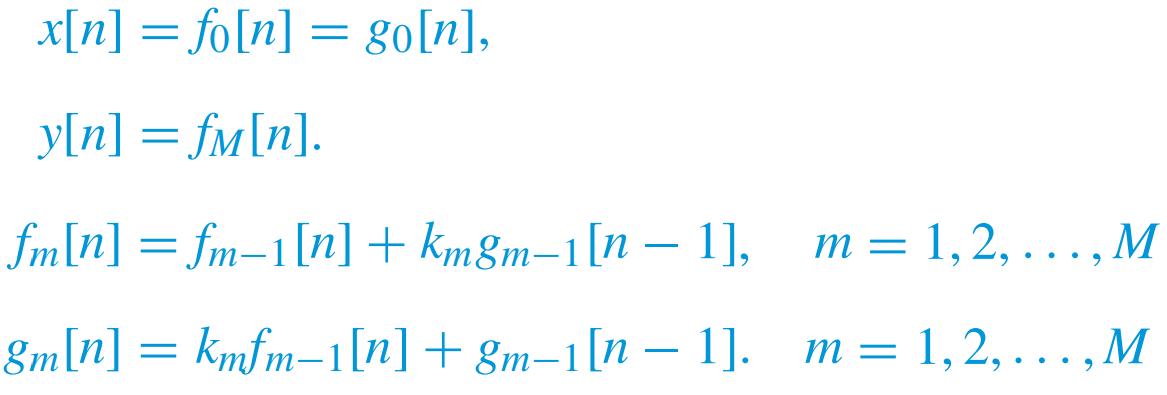

The input is $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack =\left\lbrack 1,0,0,0\right\rbrack$

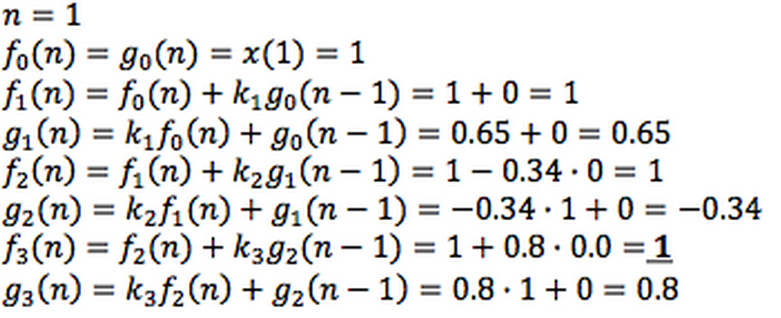

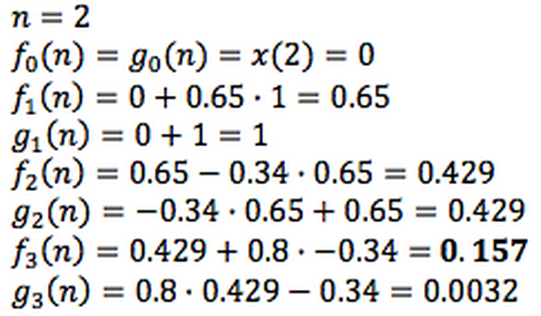

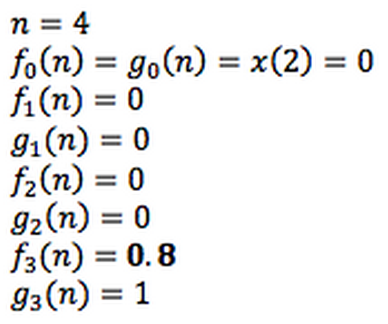

We can also use the MATLAB function **azlatfilt** given in Figure 9.26 in the book.

k = [0.65, -0.34, 0.8];
x = [1, 0, 0, 0];
G = 1;
y = azlatfilt(k, x, G)

y =     1.0000    0.1570    0.0032    0.8000


The impulse response of the given filter is:


$$h\left\lbrack n\right\rbrack =\left\lbrack 1,0\ldotp 157,0\ldotp 0032,0\ldotp 8\right\rbrack$$


## [✔] ADSI Problem 2.3: Find the reflection coefficients for an all-zero lattice filter

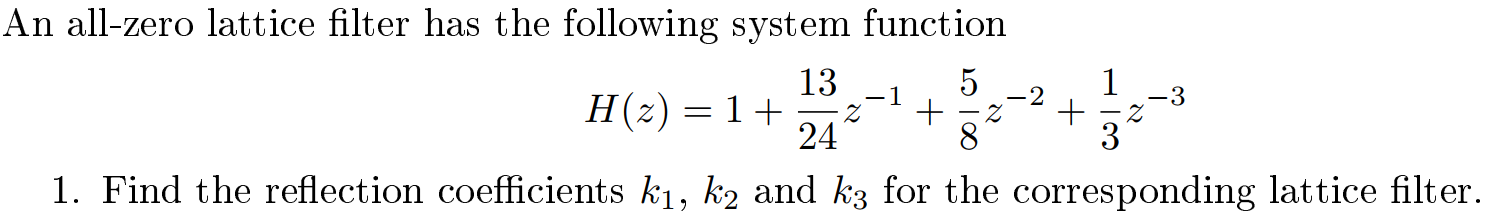

The recursive algorithm works as follows:

- Compute $A_M \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }$

- Compute $k_M =a_M$ where $a_M$ is the last coefficients of $A_M \left(z\right)$. For example, if $A_M \left(z\right)=1+0\ldotp 06z^{-1} -0\ldotp 42z^{-2} +0\ldotp 5z^{-3}$ then $k_M =0\ldotp 5$

- Compute $B_M \left(z\right)$ by flipping the coefficients of $A_M \left(z\right)$

- Set $m=M$

- Compute $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$. Notice that this is where the algorithm fails because if $k_m =1\to k_m^2 =1$ then we will have division by zero.

- Compute $k_{m-1} =a_{m-1}$ where $a_{m-1}$ is the last coefficients of $A_{m-1} \left(z\right)$

- Compute $B_{m-1} \left(z\right)$ by flipping the coefficients of $A_{m-1} \left(z\right)$. Alternatively, compute $B_{m-1} \left(z\right)=z^{-m-1} A_{m-1} \left(\frac{1}{z}\right)$

- Set $m=m-1$

- Go to step 5 if $m\not= 0$

- We know that $A_0 \left(z\right)=B_0 \left(z\right)=1$

In this problem, we have a 3-stage all-zero lattice filter:

We are given its transfer function:


$$H\left(z\right)=1+\frac{13}{24}z^{-1} +\frac{5}{8}z^{-2} +\frac{1}{3}z^{-3}$$


Since this is a FIR system of the form:


$$H\left(z\right)=\sum_{k=0}^M h\left\lbrack k\right\rbrack z^{-1}$$


We know that $M=3$, $h\left\lbrack k\right\rbrack =\left\lbrack 1,\frac{13}{24},\frac{5}{8},\frac{1}{8}\right\rbrack$ and $h\left\lbrack 0\right\rbrack =1$.

**Step 1: Compute **$A_3 \left(z\right)$


$$A_M \left(z\right)=A_3 \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }=\frac{H\left(z\right)}{1}=1+\frac{13}{24}z^{-1} +\frac{5}{8}z^{-2} +\frac{1}{3}z^{-3}$$


**Step 2: Compute **$k_3$

The last coefficients of $A_3 \left(z\right)$ is $\frac{1}{3}$ so $k_3 =\frac{1}{3}$

**Step 3: Compute **$B_3 \left(z\right)$

Once we have $A_M \left(z\right)$, we can compute $B_M \left(z\right)$ by simply flipping the coefficients of $A_M \left(z\right)$.


$$B_M \left(z\right)=B_3 \left(z\right)=\frac{1}{3}+\frac{5}{8}z^{-1} +\frac{13}{24}z^2 +z^{-3}$$


**Step 4: Set **$m=M$


$$m=3$$


**Step 5: Compute **$A_2 \left(z\right)$

Using the formula $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$ we can compute $A_2 \left(z\right)$


$$A_2 \left(z\right)=\frac{1}{1-k_3^2 }\left\lbrack A_3 \left(z\right)-k_3 B_3 \left(z\right)\right\rbrack$$



$$A_2 \left(z\right)=\frac{1}{1-{\left(\frac{1}{3}\right)}^2 }\left\lbrack \left(1+\frac{13}{24}z^{-1} +\frac{5}{8}z^{-2} +\frac{1}{3}z^{-3} \right)-\frac{1}{3}\left(\frac{1}{3}+\frac{5}{8}z^{-1} +\frac{13}{24}z^2 +z^{-3} \right)\right\rbrack$$



$$A_2 \left(z\right)=\frac{9}{8}\left\lbrack 1-\frac{1}{3}\cdot \frac{1}{3}+\left(\frac{13}{24}-\frac{1}{3}\cdot \frac{5}{8}\right)z^{-1} +\left(\frac{5}{8}-\frac{1}{3}\cdot \frac{13}{24}\right)z^{-2} +\left(\frac{1}{3}-\frac{1}{3}\right)z^{-3} \right\rbrack$$



$$A_2 \left(z\right)=\frac{9}{8}\left\lbrack \frac{8}{9}+\frac{1}{3}z^{-1} +\frac{4}{9}z^{-2} +0z^{-3} \right\rbrack$$



$$A_2 \left(z\right)=1+\frac{3}{8}z^{-1} +\frac{1}{2}z^{-2}$$


**Step 6: Compute **$k_2$

We can read of the last coefficient of $A_2 \left(z\right)$ which is $k_2 =\frac{1}{2}$

**Step 7: Compute **$B_2 \left(z\right)$

Once we have $A_2 \left(z\right)$, we can compute $B_2 \left(z\right)$ by simply flipping the coefficients of $A_2 \left(z\right)$.


$$B_2 \left(z\right)=\frac{1}{2}+\frac{3}{8}z^{-1} +z^{-2}$$


**Step 8: Set **$m=2$

Step 9: Go to step 5

**Step 5: Compute **$A_1 \left(z\right)$

We can compute $A_1 \left(z\right)$ as follows


$$A_1 \left(z\right)=\frac{1}{1-k_2^2 }\left\lbrack A_2 \left(z\right)-k_2 B_2 \left(z\right)\right\rbrack$$



$$A_1 \left(z\right)=\frac{1}{1-{\left(\frac{1}{2}\right)}^2 }\left\lbrack \left(1+\frac{3}{8}z^{-1} +\frac{1}{2}z^{-2} \right)-\frac{1}{2}\left(\frac{1}{2}+\frac{3}{8}z^{-1} +z^{-2} \right)\right\rbrack$$



$$A_1 \left(z\right)=\frac{4}{3}\left\lbrack 1-\frac{1}{2}\cdot \frac{1}{2}+\left(\frac{3}{8}-\frac{1}{2}\cdot \frac{3}{8}\right)z^{-1} +\left(\frac{1}{2}-\frac{1}{2}\right)z^{-2} \right\rbrack$$



$$A_1 \left(z\right)=\frac{4}{3}\left\lbrack \frac{3}{4}+\frac{3}{16}z^{-1} +0z^{-2} \right\rbrack$$



$$A_1 \left(z\right)=1+\frac{1}{4}z^{-1}$$


**Step 6: Compute **$k_1$

We can read of the last coefficient of $A_1 \left(z\right)$ which is $k_1 =\frac{1}{4}$

We are done! The result is $k_1 =\frac{1}{4}$, $k_2 =\frac{1}{2}$ and $k_3 =\frac{1}{3}$

Let us verify our result using the MATLAB function ***tf2latc*** to convert transfer function filter parameters to lattice filter form

b = [1, 13/24, 5/8, 1/3];
a = 1;
k = tf2latc(b, a)

k =     0.2500
    0.5000
    0.3333


We can also try the algorithm (Figure 9.24) from the book

k = fir2lat(b)

k =     0.2500    0.5000    0.3333


Both functions agree! 

The reflection coefficients are $k_1 =\frac{1}{4},k_2 =\frac{1}{2},k_3 =\frac{1}{3}$

## [✔] ADSI Problem 2.5: All-zero lattice filter, find coefficients from system function

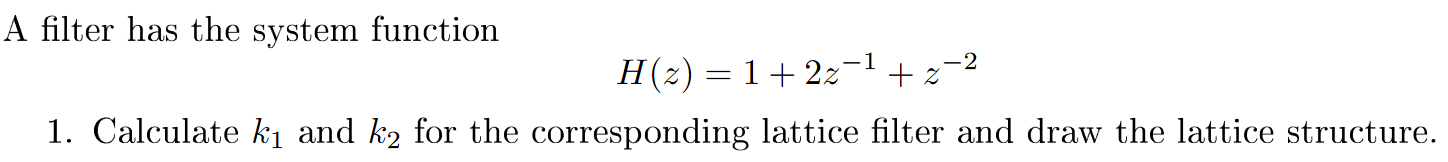

We cannot use a recursive algorithm if one of the reflection coefficients is equal to 1. In this problem, $k_2 =1$ so if we attempt to compute $A_1 \left(z\right)$, it will lead to division by zero:


$$A_1 \left(z\right)=\frac{1}{1-k_2^2 }\left\lbrack A_2 \left(z\right)-k_2 B_2 \left(z\right)\right\rbrack =\frac{1}{1-1}\left\lbrack A_2 \left(z\right)-k_2 B_2 \left(z\right)\right\rbrack$$


We can try out it out in MATLAB function:

b = [1, 2, 1];
a = 1;
% tf2latc(b) % This fails because one coeff. is 1

Instead we can use a cascade of two single-stage filters.

First, we factorise the original FIR filter to two cascade filters. This can be done by finding the roots and using the formula:

$H\left(z\right)=\left(1-r_1 z^{-1} \right)\left(1-r_2 z^{-1} \right)\cdots \left(1-r_M z^{-1} \right)$ where $r_i$ are the roots of the transfer function.

Find the roots:

roots(b)

ans =     -1
    -1


Factorise the original FIR filter into two cascading filters:


$$H\left(z\right)=\left(1-\left(-1\right)z^{-1} \right)\left(1-\left(-1\right)z^{-1} \right)=\left(1+z^{-1} \right)\left(1+z^{-1} \right)$$


Recall that that a single stage all-zero filter has following difference equation:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +k_1 x\left\lbrack n-1\right\rbrack$$


Taking the z-transform we get:


$$Y_{\mathrm{az}} \left(z\right)=X_{\mathrm{az}} \left(z\right)+k_1 X_{\mathrm{az}} \left(z\right)z^{-1}$$


The system function of a single stage all-zero lattice filter is therefore:


$$H_{\mathrm{az}} \left(z\right)=\frac{Y_{\mathrm{az}} \left(z\right)}{X_{\mathrm{az}} \left(z\right)}=1+k_1 z^{-1}$$


It turns out that we can cascade two single stage all-zero lattice filters the same way as we cascade FIR filters.

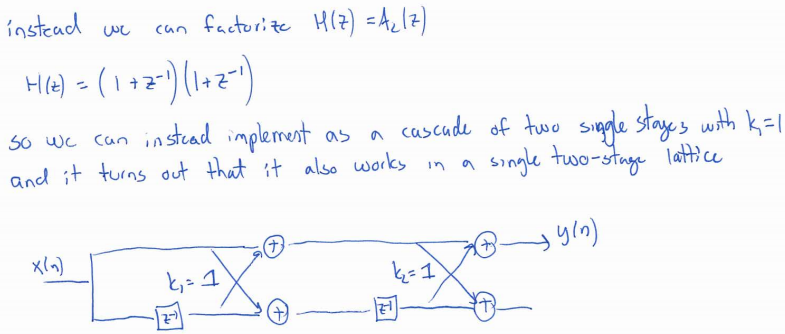

So in our case, we have $k_1 =1$ and $k_2 =1$.

Let us check if we can get the impulse response of the original filter.

k = [1, 1];
lat2fir(k, 1)

ans =      1     2     1


latc2tf(k) % Same as lat2fir

ans =      1     2     1


Success! 

## [✔] ADSI Problem 2.7: Find system function an all-pole filter from reflection coefficients

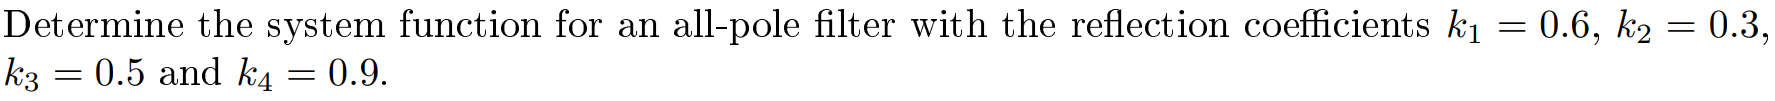

We can do this by hand using following two formulas:


$$f_{m-1} \left\lbrack n\right\rbrack =f_m \left\lbrack n\right\rbrack -k_m g_{m-1} \left\lbrack n-1\right\rbrack$$



$$g_m \left\lbrack n\right\rbrack =k_m f_{m-1} \left\lbrack n\right\rbrack +g_{m-1} \left\lbrack n-1\right\rbrack$$


We start computing the difference equations of the last section:


$$f_0 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack$$



$$g_1 \left\lbrack n\right\rbrack =k_1 f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack$$


Then we compute the next stage:


$$f_1 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack$$



$$g_2 \left\lbrack n\right\rbrack =k_2 f_1 \left\lbrack n\right\rbrack +g_1 \left\lbrack n-1\right\rbrack$$


Next, we can substitute $f_1 \left\lbrack n\right\rbrack$ into the expression $f_0 \left\lbrack n\right\rbrack$:


$$\begin{array}{l}
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack \\
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 \left(k_1 f_0 \left\lbrack n-1\right\rbrack +g_0 \left\lbrack n-2\right\rbrack \right)-k_1 g_0 \left\lbrack n-1\right\rbrack 
\end{array}$$


And so on. 

Finally, we will get a large expression in which we replace:

- $g_0 \left\lbrack n\right\rbrack$ and $f_0 \left\lbrack n\right\rbrack$ with $y\left\lbrack n\right\rbrack$

- $f_4 \left\lbrack n\right\rbrack$ with $x\left\lbrack n\right\rbrack$

Alternatively, we can use MATLAB to compute the transfer function:

k = [0.6, 0.3, 0.5, 0.9];
[num, dem] = latc2tf(k, 'allpole')

num =      1     0     0     0     0


dem =     1.0000    1.3800    1.3110    1.3370    0.9000


The system function is:


$$H\left(z\right)=\frac{1}{1+1\ldotp 38z^{-1} +1\ldotp 311z^{-2} +1\ldotp 337z^{-3} +0\ldotp 9z^{-4} }$$


## ADSI Problem 2.10: Linear prediction and lattice filters  

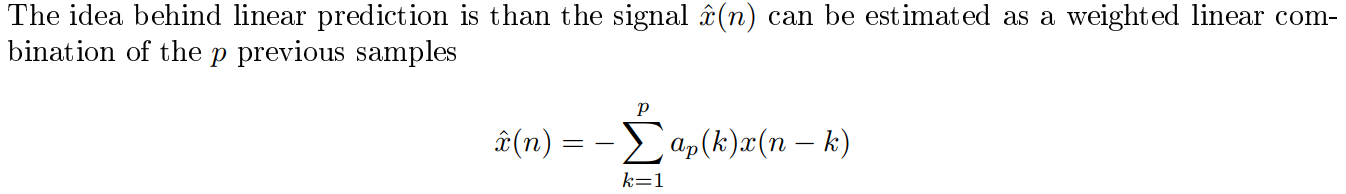

### 1) Compute autocorrelation from a signal

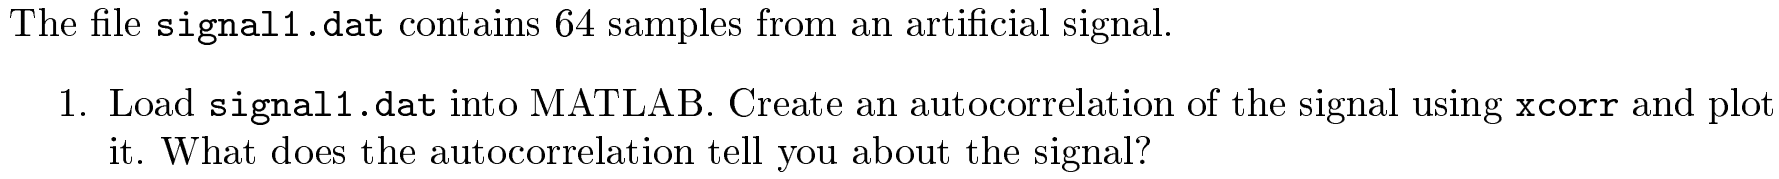

Let us first plot the signal.

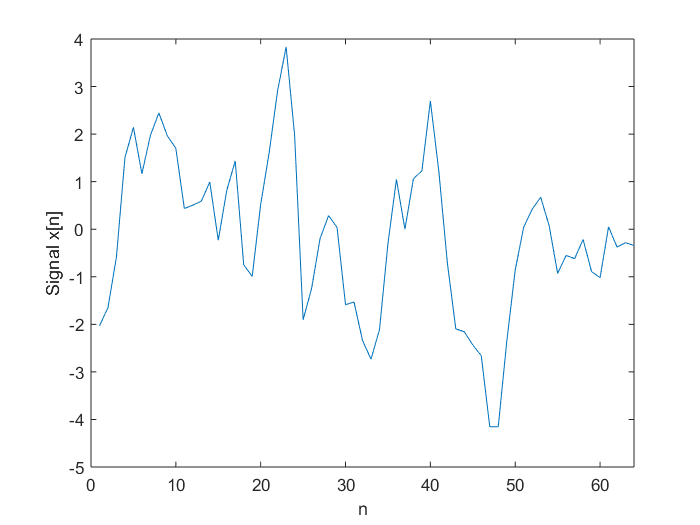

x = importdata('signal1.dat');
plot(x);
xlabel('n');
ylabel('Signal x[n]');
xlim([0, numel(x)]);

Autocorrelation is the cross-correlation between a signal $x\left\lbrack n\right\rbrack$ with the same signal shifted by some amount $x\left\lbrack n-k\right\rbrack$. So if we start with $k=1$, we compute the correlation between $x\left\lbrack n\right\rbrack$ and $x\left\lbrack n-1\right\rbrack$. For $k=2$, we compute the correlation between $x\left\lbrack n\right\rbrack$ and $x\left\lbrack n-2\right\rbrack$ etc.

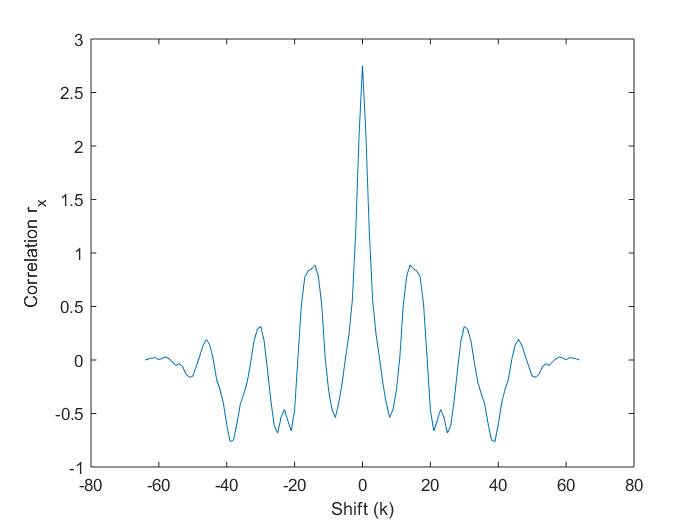

% r = xcorr(x) returns the autocorrelation sequence of x
[r,lags] = xcorr(x,64,'biased');
plot(lags,r);
xlabel('Shift (k)');
ylabel('Correlation r_x');

From the plot, we see that when the signal is shifted e.g. by 4, the correlation is low. 

r(50)

ans = 1

ans = 0.8533

r(50)

ans = 0.8533

This means that the original signal $x\left\lbrack n\right\rbrack$ and the shifted signal $x\left\lbrack n-4\right\rbrack$ are not very similar. The correlation is a lot higher 56 when the signal is shifted by 50:

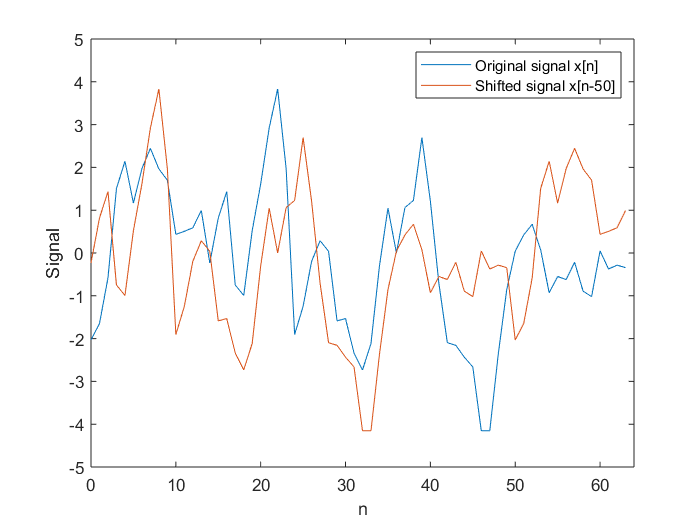

n = linspace(0, 63, 64)';
x_shifted_50 = circshift(x, 50);
plot(n, x, n, x_shifted_50);
legend('Original signal x[n]','Shifted signal x[n-50]')
xlabel('n');
ylabel('Signal');
xlim([0, numel(x)]);
ylim([-5, 5])

Shifting the signal by 64 yields the highest correlation. This makes sense because if we shift a signal of length 64 by 64 then we get the original signal $x\left\lbrack n\right\rbrack =x\left\lbrack n-64\right\rbrack$.

### 2) Compute the optimum second-order linear predictor

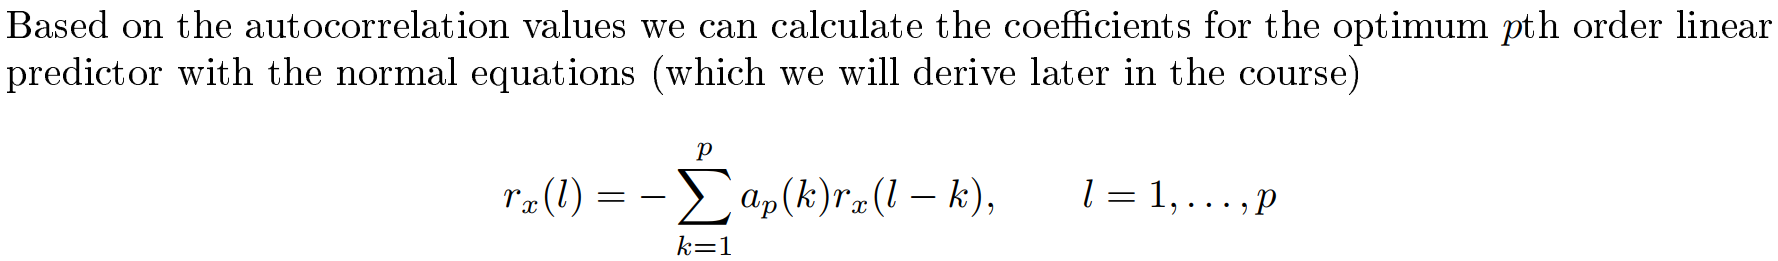

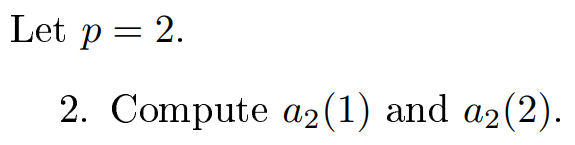

When $p=2$ then we have:


$$r_x \left(l\right)=-a_2 \left(1\right)r_x \left(l-1\right)-a_2 \left(2\right)r_x \left(l-2\right)$$


### 3) Compare the linear predictor with a two-stage all-zero lattice filter

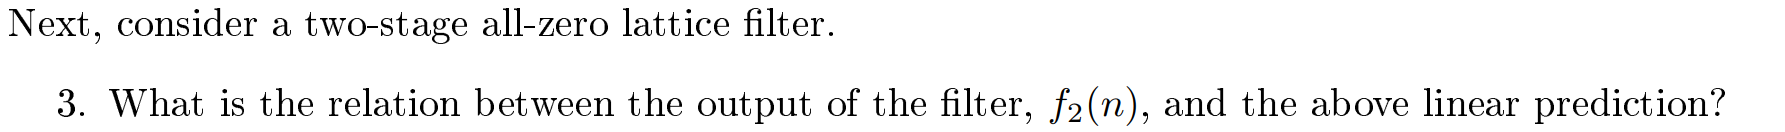

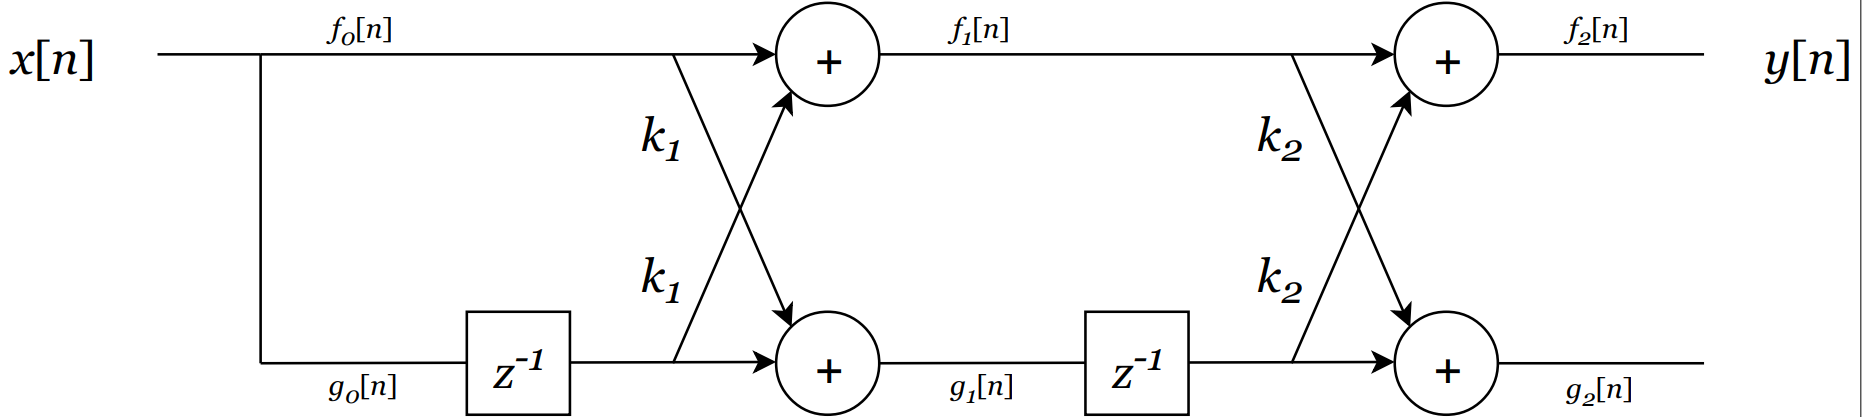

We know that the output of a two-stage all-zero lattice filter is:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +k_1 \left(1+k_2 \right)x\left\lbrack n-1\right\rbrack +k_2 x\left\lbrack n-2\right\rbrack$$


Suppose $x\left\lbrack n\right\rbrack =0$. By pattern matching, we can say that:

$k_1 \left(1+k_2 \right)=-a_2 \left(1\right)$ and $k_2 =-a_2 \left(2\right)$

### 4) Compute reflection coefficients from the linear predictor

### 5) Compute prediction error

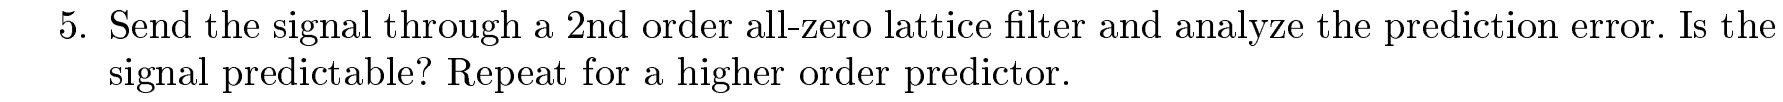

## ADSI Problem 2.11 (Optional): The digital state variable filter

One interesting filter structure is the digital state variable filter which has its roots in the analog state variable filter. It can be considered as a standard second order filter, but with the valuable feature that the center frequency and Q-factor are independently tuneable. The structure of the filter is shown here  

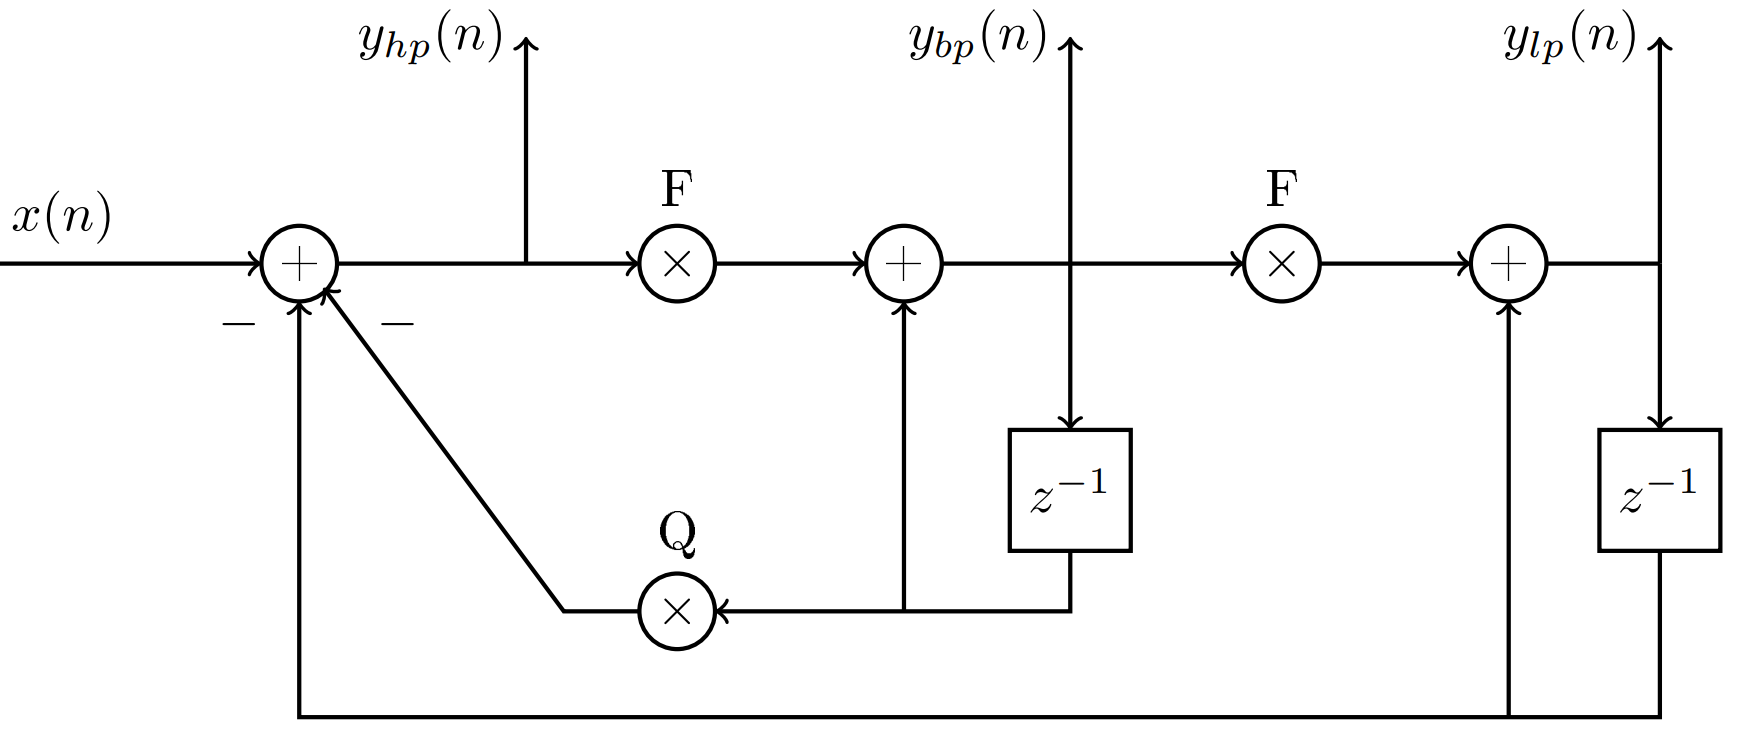

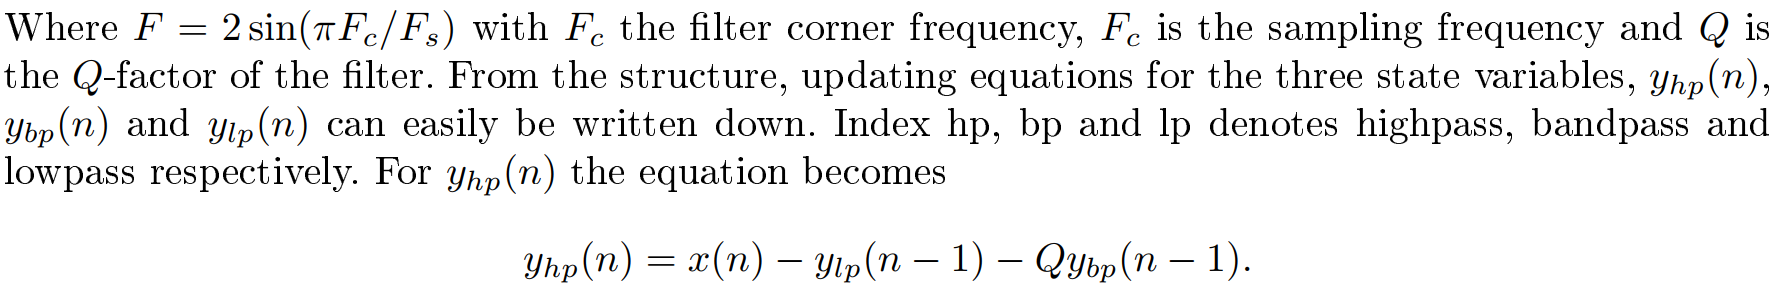

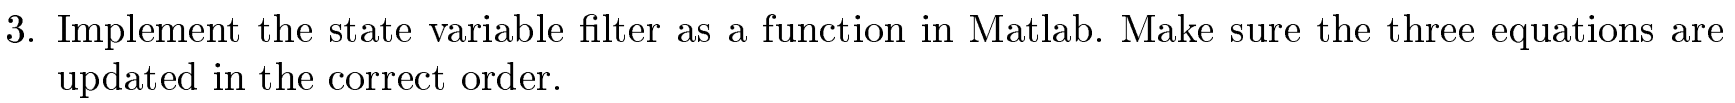

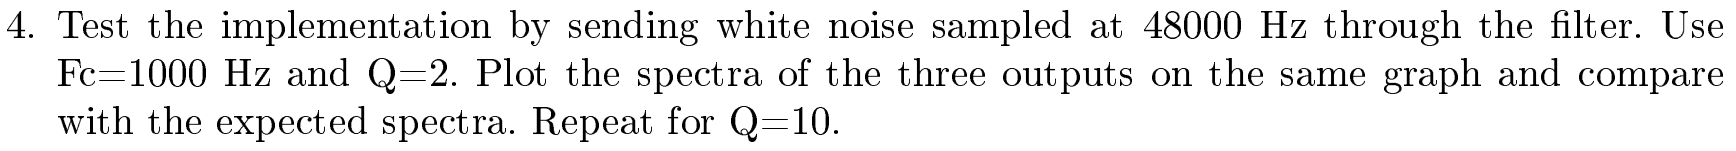

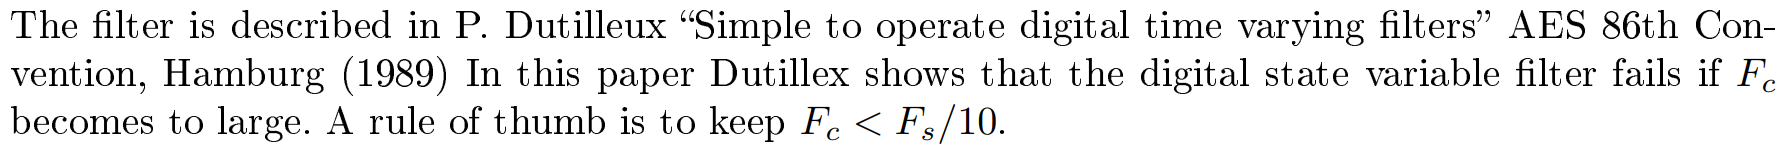

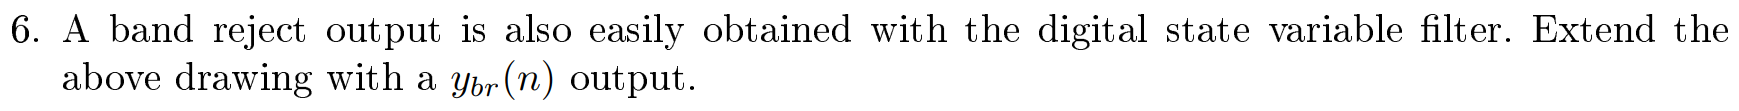

## Functions

function [y] = azlatfilt(k, x, G)
% AZLATFILT      Function for implementation of an all-zero FIR lattice filter
% From Figure 9.26 (p 515)

    M = length(k); 
    
    % Create an array for the sequence f_m[n]
    f = zeros(1,M); 
    
    % Create an array for the sequence g_m[n]
    g = f;
    
    % Create an array for the sequence g_m[n-1]
    oldg = zeros(1,M);
    
    % Keeps track of x[n-1]
    oldx = 0;
    x = G*x; 
    y = zeros(size(x));
    
    for n=1:length(x)
        % Compute f1[n] = x[n] + k1x[n ? 1] -> Equation (9.57a)
        f(1) = x(n)+k(1)*oldx;
        
        % Compute g1[n] = k1x[n] + x[n ? 1] -> Equation (9.57b)
        g(1) = k(1)*x(n)+oldx;
        oldx = x(n);
        for m = 2:M
            % Compute: fm[n] = fm?1[n] + km gm?1[n ? 1] -> Equation (9.55a)
            f(m) = f(m-1)+k(m)*oldg(m-1);
            
            % Compute: gm[n] = km fm?1[n] + gm?1[n ? 1] -> Equation (9.55b)
            g(m) = k(m)*f(m-1)+oldg(m-1);
            
            % Delay
            oldg(m-1) = g(m-1);
        end
        
        % y[n] = fM[n] -> Equation (9.56b)
        y(n) = f(M);
    end
end


function [k,G] = fir2lat(h)
% Converts FIR filter coefficients to lattice coefficients.
% From Figure 9.24 (p. 514)
    G = h(1); 
    a = h/G;
    M = length(h)-1; 
    k(M) = a(M+1);
    for m = M:-1:2
        b = fliplr(a);
        a = (a-k(m)*b)/(1-k(m)^2); a = a(1:m);
        k(m-1) = a(m);
    end
end

function h = lat2fir(k, G)
% Converts lattice coefficients to FIR filter coefficients.
% From Figure 9.25 (p. 515)
    a = 1; 
    b = 1; 
    M = length(k);
    for m = 1:1:M
        a = [a,0]+k(m)*[0,b];
        b = fliplr(a);
    end
    h = G*a;
end
